# HW3 Example

## 1. 문제정의와 기본 근궤적 그리기

clc; clear
% [Problem] 1. 개루프 전달함수 G(s)H(s)를 설계하시오.
s = tf('s');
otf = 1/((s+1)*(s+4)*(s+6))

otf =
 
             1
  ------------------------
  s^3 + 11 s^2 + 34 s + 24
 
연속시간 전달 함수입니다.



% [Problem] 2. 시스템이 달성할 수 있는 적절한 목표 성능을 2가지 제시하시오.
os = 0.16;  % 최대초과비율
ts = 2;     % 정착시간
% 근궤적 그리기
rlocus(otf)
hold on

## 2. 성능 경계선과 목표 극점 그리기

% [Problem] 3-1. 첫 번째 목표성능의 성능 경계선을 그리는 코드를 작성하시오.
% [Problem] 3-2. 두 번째 목표성능의 성능 경계선을 그리는 코드를 작성하시오

% [Problem] 4. (필기) 두 성능 조건을 만족하는 극점의 위치를 계산하시오.
target_pole = -2.0000 + 1i*3.4286;
pole_real = real(target_pole);
pole_imag = imag(target_pole);
fprintf('조건을 만족하는 극점의 위치 s = %.4f + j%.4f\n', pole_real, pole_imag)

조건을 만족하는 극점의 위치 s = -2.0000 + j3.4286


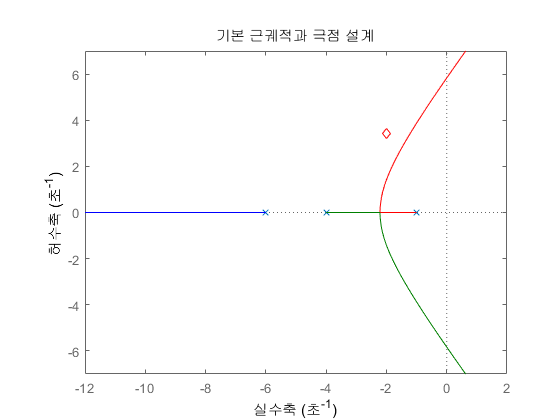

plot(pole_real, pole_imag, 'rd')
hold off
axis([-12 2 -7 7])
title('기본 근궤적과 극점 설계')

## 3. PD 제어기 설계

% [Problem] 5. (필기) 근궤적이 target pole을 지나기 위한 영점을 계산하시오.
zero_pd = -8.8452

zero_pd = -8.8452

% PD 제어기를 반영한 근궤적
otf_pd = otf * (s - zero_pd)

otf_pd =
 
         s + 8.845
  ------------------------
  s^3 + 11 s^2 + 34 s + 24
 
연속시간 전달 함수입니다.



K = -1/evalfr(otf_pd, target_pole);
K = real(K);
fprintf("PD 제어기 적용 후 target pole에서의 상수 이득 K=%1.4f\n", K)

PD 제어기 적용 후 target pole에서의 상수 이득 K=9.7552


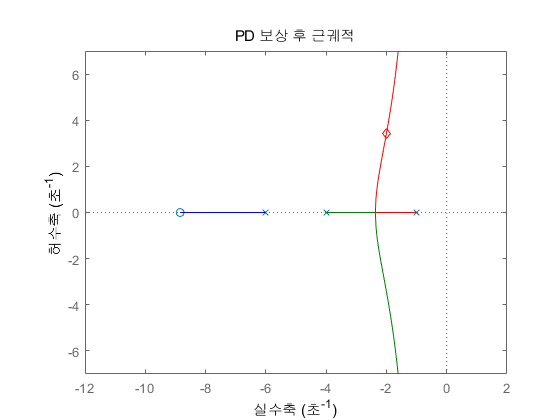

rlocus(otf_pd)
hold on
plot(real(target_pole), imag(target_pole), 'rd')
hold off
title('PD 보상 후 근궤적')
axis([-12 2 -7 7])

## 4. 제어기 성능 확인

% [Problem] 6. 제어기를 포함한 폐루프 시스템의 전달함수를 구하시오.
% [Problem] 7. 폐루프 시스템의 전달함수로부터 단위계단응답 그래프를 그리시오.
% [Problem] 8. 단위계단응답의 다양한 과도응답 성능을 계산하시오.